**Load CSV data into Matlab Table**

Before you start, clean up the data: NaN are not allowed.

Load a csv file:

% path and file name
path = "/home/andri/repos/ip8-roboter-energy-management/matlab/bat_characterization_data.csv";
T = readtable(path);

% print first values of the csv file
T

T = 1083817×3 table
    time     voltage    current
    _____    _______    _______

        0    13.555        0   
      0.2    13.551        0   
    0.306    13.551        0   
    0.406    13.551        0   
    0.513    13.551        0   
    0.615    13.551        0   
    0.716    13.551        0   
    0.817    13.551        0   
    0.918    13.551        0   
    1.026    13.551        0   
    1.135    13.547        0   
    1.244    13.551        0   
    1.352    13.551        0   
    1.461    13.551        0   
    1.562    13.551        0   
    1.669    13.551        0   


Create a new matlab datastructure:

signals(1:3) = struct('values', [], 'dimensions', [], 'label', '');
signals(1).label = "time";
signals(1).values = T.time;
signals(1).dimensions = length(T.time);

signals(2).label = "current";
signals(2).values = T.current;
signals(2).dimensions = length(T.current);

signals(3).label = "voltage";
signals(3).values = T.voltage;
signals(3).dimensions = length(T.voltage);

hppc_mat = struct('signals', signals);

Create a battery pulse sequence object:


% https://ch.mathworks.com/help/autoblks/ug/estimate-equivalent-circuit-lithium-ion-battery-data.html

psObj = Battery.PulseSequence;
psObj.ModelName = 'BatteryEstim2RC_PTBS';
time = hppc_mat.signals(1).values;
current = hppc_mat.signals(2).values;
voltage = hppc_mat.signals(3).values;

psObj.addData(time,voltage,current);

Identify pulses:

psObj.createPulses(...
    'CurrentOnThreshold',10.0,...
    'NumRCBranches',2,... %how many RC pairs in the model
    'RCBranchesUse2TimeConstants',false,... %do RC pairs have different time constant for discharge and rest?
    'PreBufferSamples',10,... %how many samples to include before the current pulse starts
    'PostBufferSamples',15); %how many samples to include after the next pulse starts

% psObj.plotIdentifiedPulses();
% psObj.removePulses(psObj.NumPulses -1);
psObj.plotIdentifiedPulses();


PulsesToTest = [1 floor(psObj.NumPulses/2), (psObj.NumPulses -1)];
psObj.Pulse(PulsesToTest).compareRelaxationTau();

Plot results:

Params = psObj.Parameters;

Params.EmMin(:) = 10.5;

Params.EmMax(:) = 13.8;
Params.Em(:) = 12.8;

Params.Tx(1,:,:) = 7;
Params.Tx(2,:,:) = 50;

Params.TxMin(1,:,:) = 1;
Params.TxMax(1,:,:) = 50;

Params.TxMin(2,:,:) = 20;
Params.TxMax(2,:,:) = 3500;

psObj.Parameters = Params;

disp(psObj);

  PulseSequence with properties:

                 Data: [1083817×5 double]
            ModelName: 'BatteryEstim2RC_PTBS'
             MetaData: [1×1 Battery.MetaData]
             Capacity: 2.0546e+05
           CapacityAh: 57.0721
            NumPulses: 32
             TestType: 'discharge'
                 Time: [1083817×1 double]
              Voltage: [1083817×1 double]
              Current: [1083817×1 double]
               Charge: [1083817×1 double]
             ChargeAh: [1083817×1 double]
                  SOC: [1083817×1 double]
           Parameters: [1×1 Battery.Parameters]
    ParametersHistory: [1×2 Battery.Parameters]
              idxEdge: [128×1 double]
              idxLoad: [32×2 double]
             idxRelax: [32×2 double]
                Pulse: [32×1 Battery.Pulse]




psObj.estimateInitialEmR0(...
    'SetEmConstraints',true,... %Update EmMin or EmMax values based on what we learn here
    'EstimateEm',true,... %Keep this on to perform Em estimates
    'EstimateR0',true); %Keep this on to perform R0 estimates

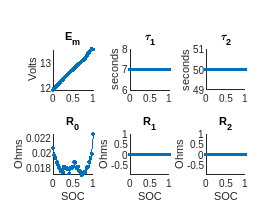

psObj.plotLatestParameters();

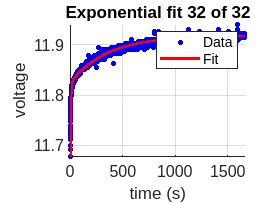


psObj.estimateInitialTau(...
    'UpdateEndingEm',true,... %Keep this on to update Em estimates at the end of relaxations, based on the curve fit
    'ShowPlots',true,... %Set this true if you want to see plots while this runs
    'ReusePlotFigure',true,... %Set this true to overwrite the plots in the same figure
    'UseLoadData',false,... %Set this true if you want to estimate Time constants from the load part of the pulse, instead of relaxation
    'PlotDelay',0.5); %Set this to add delay so you can see the plots 

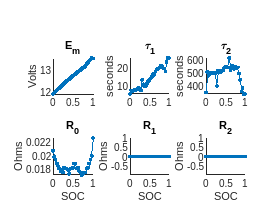


psObj.plotLatestParameters();

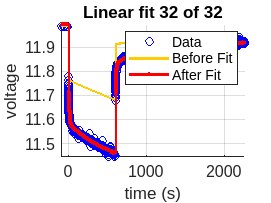


psObj.estimateInitialEmRx(...
    'IgnoreRelaxation',false,... %Set this true if you want to ignore the relaxation periods during this step
    'ShowPlots',true,...  %Set this true if you want to see plots while this runs
    'ShowBeforePlots',true,... %Set this true if you want to see the 'before' value on the plots
    'PlotDelay',0.5,... %Set this to add delay so you can see the plots 
    'EstimateEm',true,... %Set this true to allow the optimizer to change Em further in this step
    'RetainEm',true,... %Set this true keep any changes made to Em in this step
    'EstimateR0',true,... %Set this true to allow the optimizer to change R0 further in this step
    'RetainR0',true); %Set this true keep any changes made to R0 in this step

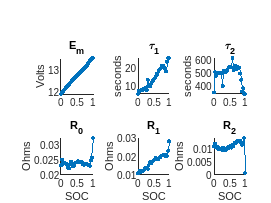


psObj.plotLatestParameters();

Params = psObj.Parameters;

Optimization:

% psObj.plotSimulationResults(); 
% 
% delete(gcp('nocreate'));
% parpool('Processes',4);
% 
% SDOOptimizeOptions = sdo.OptimizeOptions(...
%     'OptimizedModel',psObj.ModelName,...
%     'Method','lsqnonlin',...
%     'UseParallel','always');
% 
% SDOOptimizeOptions.MethodOptions.Display = 'final';
% 
% psObj.estimateParameters(...
%     'CarryParamToNextPulse',true,... %Set this true to use the final parameter values from the prior pulse and SOC as initial values for the next pulse and SOC
%     'SDOOptimizeOptions',SDOOptimizeOptions,... %Specify the SDO options object
%     'ShowPlots',true,... %Set this true if you want to see plots while this runs
%     'EstimateEm',true,... %Set this true to allow the optimizer to change Em further in this step
%     'RetainEm',true,... %Set this true keep any changes made to Em in this step
%     'EstimateR0',true,... %Set this true to allow the optimizer to change R0 further in this step
%     'RetainR0',true); %Set this true keep any changes made to R0 in this step
% 
% 
% psObj.plotLatestParameters();
% psObj.plotSimulationResults();

Export data:

% EmPrime = repmat(Em,2,1)';
% R0Prime = repmat(R0,2,1)';
% SOC_LUT   1Prime = SOC_LUT;
% TempPrime = 303;
% CapacityAhPrime = [CapacityAh];
% R1Prime = repmat(Rx(1,:),2,1)';
% C1Prime = repmat(Tx(1,:)./Rx(1,:),2,1)';
% R2Prime = repmat(Rx(2,:),2,1)';
% C2Prime = repmat(Tx(2,:)./Rx(2,:),2,1)';
vars = {'R0','R1','R2','T1','T2','Em','SOC','P','Q','R'};

R0 = psObj.Parameters.R0'

R0 =     0.0231
    0.0250
    0.0236
    0.0240
    0.0238
    0.0237
    0.0234
    0.0226
    0.0222
    0.0236


R1 = psObj.Parameters.Rx(1,:)'

R1 =     0.0107
    0.0114
    0.0123
    0.0117
    0.0119
    0.0122
    0.0126
    0.0136
    0.0141
    0.0136


R2 = psObj.Parameters.Rx(2,:)'

R2 =     0.0110
    0.0121
    0.0108
    0.0106
    0.0108
    0.0101
    0.0102
    0.0102
    0.0098
    0.0106


SOC = psObj.Parameters.SOC

SOC =          0    0.0312    0.0625    0.0937    0.1250    0.1562    0.1875    0.2188    0.2500    0.2813    0.3125    0.3438    0.3750    0.4063    0.4375    0.4688    0.5000    0.5312    0.5625    0.5937    0.6250    0.6562    0.6875    0.7187    0.7500    0.7812    0.8125    0.8437    0.8750    0.9063    0.9375    0.9687    1.0000


T1 = psObj.Parameters.Tx(1,:)'

T1 =     5.3737
    7.3717
    7.1483
    7.2409
    7.6666
    7.7216
    8.1664
    8.6043
    8.4964
    7.4644


T2 = psObj.Parameters.Tx(2,:)'

T2 =   352.0644
  506.7456
  478.8009
  491.7981
  500.7124
  496.8126
  497.1353
  504.0734
  500.3791
  400.8171


Em = psObj.Parameters.Em'

Em =    11.9174
   11.9867
   12.0416
   12.0948
   12.1483
   12.2021
   12.2525
   12.3038
   12.3529
   12.4183



R0 = repmat(R0,1,2);
R1 = repmat(R1,1,2);
R2 = repmat(R2,1,2);
T1 = repmat(T1,1,2);
T2 = repmat(T2,1,2);
Em = repmat(Em,1,2);

T = [300, 301]

T =    300   301



P = diag([1e-6 1e-6 1]); 
Q = 1e-4 * eye(3); % uncertainty of process model
R = 0.7 % unvertainty of measuremtents

R = 0.7000

AH = 44

AH = 44

Ts = 0.1

Ts = 0.1000